clearvars
close all
load data.txt
load settings.txt %Как один из вариантов
dv = settings(1)

dv = 0.0134

dt = settings(2)

dt = 0.0110

u = data*dv

u =     0.0134
    0.0670
    0.0938
    0.1206
    0.1474
    0.2010
    0.2278
    0.2546
    0.3082
    0.3082


t = ((1:length(data))*dt)'

t =     0.0110
    0.0220
    0.0330
    0.0440
    0.0550
    0.0660
    0.0770
    0.0880
    0.0990
    0.1100


f1 = figure("Name","Aсочакова Анна Б03-004")

f1 =   Figure (1: Aсочакова Анна Б03-004) with properties:

      Number: 1
        Name: 'Aсочакова Анна Б03-004'
       Color: [0.9400 0.9400 0.9400]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


plot(t,u,"M--o","LineWidth",0.5, "MarkerIndices",1:15:length(data),"MarkerSize",4)
grid on
title(["Зависимость ","напряжения конденсатора", "в RC цепочке"])
xlabel("Время,с")
ylabel("Напряжение,В")
legend("u(t)")
set(gcf,"Visible","on")
[row,con] = find(u==max(u))

row = 384

con = 1

m = length(max(u))

m = 1

u1 = u(1:row)

u1 =     0.0134
    0.0670
    0.0938
    0.1206
    0.1474
    0.2010
    0.2278
    0.2546
    0.3082
    0.3082


t1 = dt*(1:length(u1))'

t1 =     0.0110
    0.0220
    0.0330
    0.0440
    0.0550
    0.0660
    0.0770
    0.0880
    0.0990
    0.1100


tcharge = t1(end,1)

tcharge = 4.2240

t2 = dt*(length(u1):length(t))'

t2 =     4.2240
    4.2350
    4.2460
    4.2570
    4.2680
    4.2790
    4.2900
    4.3010
    4.3120
    4.3230


tdischarge = t2(end,1) - t1(end,1)

tdischarge = 5.6540

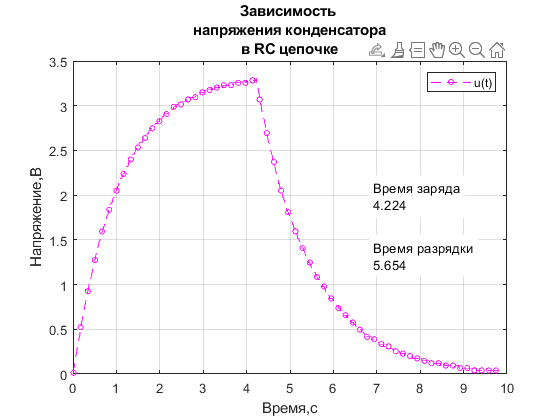

text(max(t)*0.7,max(u)*0.6,["Время заряда";num2str(tcharge)],"BackgroundColor","w")
text(max(t)*0.7,max(u)*0.4,["Время разрядки";num2str(tdischarge)],"BackgroundColor","w")
saveas(f1,"capacitor.svg")
saveas(f1,"capacitor.png")